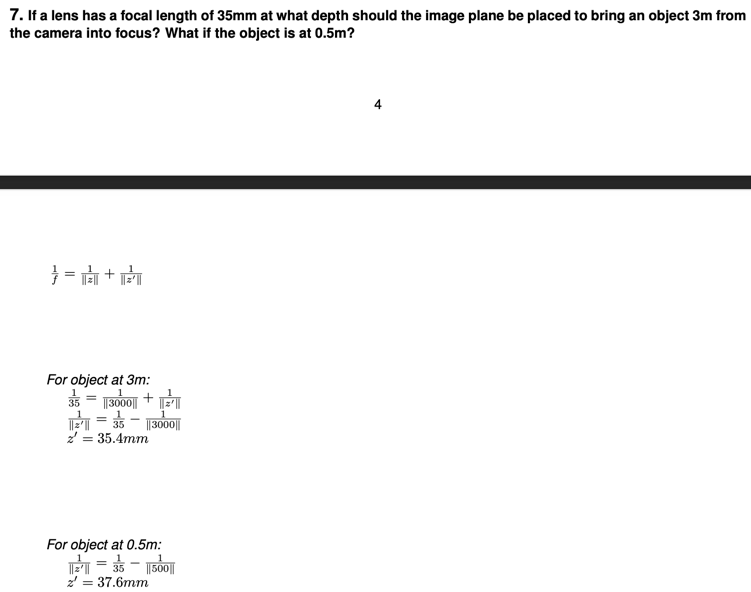

f = 35;
z = 3 * 1000;
find_depth(f,z)

ans = 35.4132


f = 35;
z = 0.5 * 1000;
find_depth(f,z)

ans = 37.6344

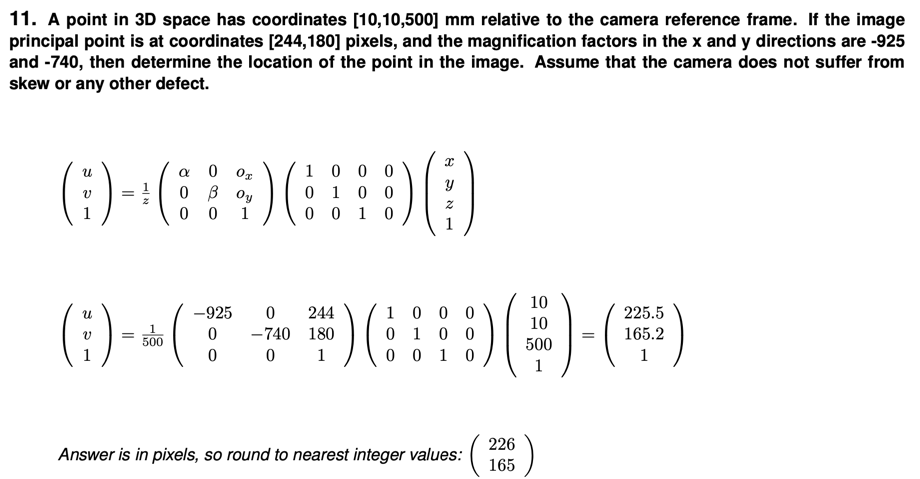

principal_point = [244 180]

principal_point =    244   180


x = -925

x = -925

y = -740

y = -740

p = [10 10 500]

p =     10    10   500



location_in_img(x,y,principal_point,p)

ans =   225.5000
  165.2000
    1.0000


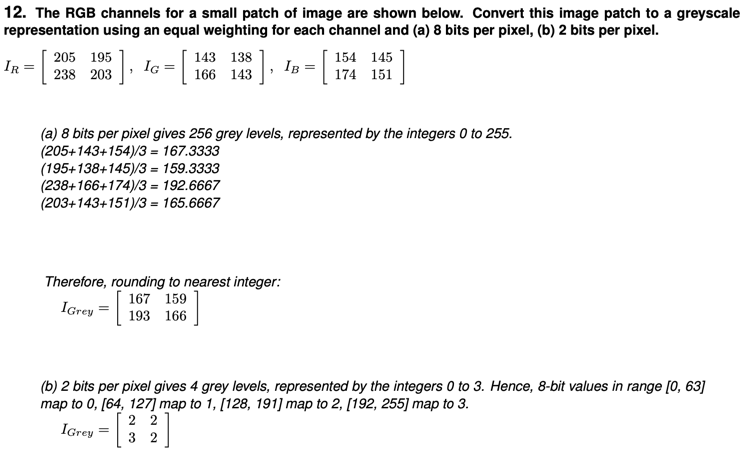

IR = [205 195
      238 203];
IG = [143 138
      166 143];
IB = [154 145
      174 151];

img(:,:,1) = IR;
img(:,:,2) = IG;
img(:,:,3) = IB;

% 8bit
I_gray_8 = mean(img,3)

I_gray_8 =   167.3333  159.3333
  192.6667  165.6667



% 2bit
I_gray_2 = zeros(2);
for i = 1:4
    if I_gray_8(i) <= 63
        I_gray_2(i) = 0;
    
    elseif I_gray_8(i) <= 127
        I_gray_2(i) = 1;
    elseif I_gray_8(i) <= 191
        I_gray_2(i) = 2;
    else
        I_gray_2(i) = 3;
    end
end

I_gray_2

I_gray_2 =      2     2
     3     2


function out = find_depth(f,z)
    out = 1/ (1/f - 1/z);
end

function out = location_in_img(x,y,principal_point,p)
    matrix = [x 0 principal_point(1) 0
              0 y principal_point(2) 0
              0 0 1 0];
    p_T = p.';
    p_T(4) = 1;
    out = 1/p(3) * matrix * p_T;
end